# cAMPFreSimulation_Interactive1

Shuai Yang 2023/2/17

优化用于模拟的参数设置。可参考cAMPFreSimulation_Interactive

#### 参数定义与选择

P = 0.1; % 占空比(0,1]
gamma = 0.002876;% s-1,cAMP降解率 gamma;
beta = 0.2; % s-1, bPAC失活率
alpha =0.00225;% alpha = k/K1;调节Vfr-cAMP2浓度
lambda = 27;% lambda = Vfr/K2;调节激活DNA。

#### % 数值积分模拟蛋白输出

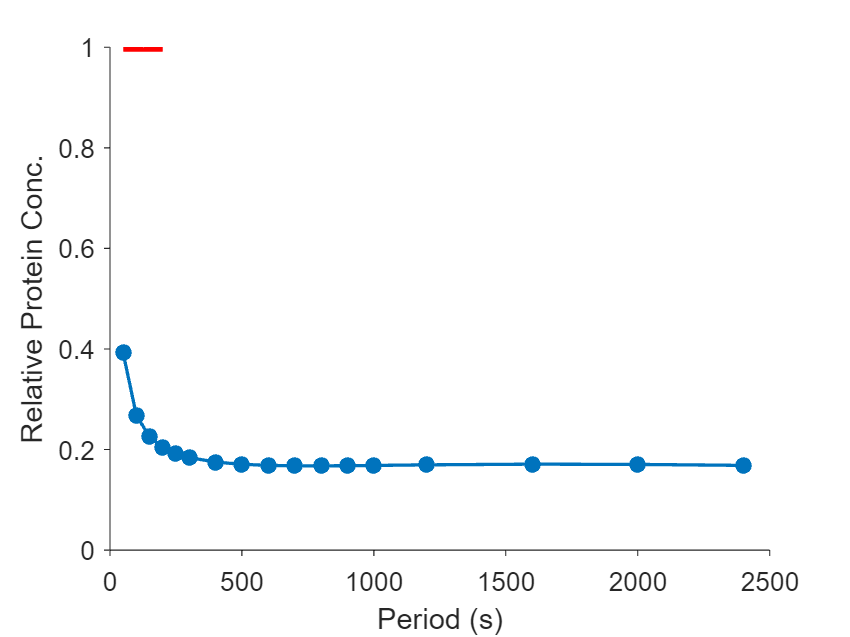

xlog = false;
Tset = [50:50:300,400:100:1000,1200:400:2400];
f1 = meanProPlt1(Tset,gamma,beta,P,alpha,lambda);


if xlog
    ax1 = f1.CurrentAxes;
    set(ax1,'XScale','log')
end

**% 参数说明及默认参数设置**

% % k= k0[bPAC*], uM/s；光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率
% k = 0.0045; % uM/s;cAMP生产 包含在参数alpha中
% % cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
% % Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数 n2
% n1 = 2; % 暂时不用
% K1 =2; % 2 uM 包含在参数alpha中
% n2 = 2; % 暂时不用
% K2 = 0.01; % 0.01uM = 10 nM 包含在参数lambda中
% % alpha = k/K1;
% % 基因元件数目
% Vfr = 0.27;% 0.27uM TF因子数目 包含在参数lambda中
% DNA = 0.05; % 0.05uM 启动子的DNA数目
% % lambda = Vfr/K2;
% % 蛋白表达
% gamma2 = 0.00027;  %蛋白的降解率 2.7e-4 s-1
% k2 = 0.12 ;% s-1 蛋白生产率 = 转录率*翻译率/mRNA降解率 = 0.02*0.03/0.005
% ymax = k2/gamma2*DNA;% 蛋白的最大表达量 uM

cAMP浓度的变化$x(t)$：

function x1 = cAMPOutPut1(t,T,gamma,beta,P)

x_Mid1 = (1/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
    +1/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
x_Low1 = x_Mid1*exp(-gamma*(T-T*P))...
    +1/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));

x1 = ((x_Low1-1/gamma)*exp(-gamma*t)+1/gamma).*(t<=T*P)+...
    ((x_Mid1+1/(beta-gamma))*exp(-gamma*(t-T*P)) ...
    -1/(beta-gamma)*exp(-beta*(t-T*P))).*(t>T*P);

end

function u1 = actDNAOutPut1(t,T,gamma,beta,P,alpha,lambda)
% t 时间 T 周期

x1 = cAMPOutPut1(t,T,gamma,beta,P);
u1 = lambda./((1+lambda)+1./(x1*alpha).^2);

end

function f1 = meanProPlt1(Tset,gamma,beta,P,alpha,lambda)

y = NaN(size(Tset));
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    fun =@(t,T) actDNAOutPut1(t,T,gamma,beta,P,alpha,lambda);
    q = integral(@(t) fun(t,T),0,T);
    q1 = q/T;
    y(iPeroid) = q1;
end

f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset,y,'Marker','o','MarkerSize',6, ...
    'MarkerFaceColor',[0,0.45,0.74],'Color',[0,0.45,0.74],'LineWidth',1.5);
hold on
line([50,200],[1,1],'LineWidth',4,'Color','r')
ylim(ax1,[0,1]);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Relative Protein Conc.')
end
